# K-nearest neighbours classification

## Overview

In this lab we're going to concentrate on k-nearest neighbours (k-NN) classification. Following the lecture, and perhaps with a bit of extra follow-up work, this is a classifier we are hoping you will understand well enough to implement for yourself! If you can already see how to do that, then great, please jump in. Complete the `my_ClassificationKNN` class and supporting `my_fitcknn()` function, and check your finished code produces the same results as the built-in `fitcknn()` functionality. 

If you're not so sure how to proceed, then first don't worry, as k-NN is really pretty easy (much easier than Naive Bayes last time), and second, the tasks below try to help you through the process of re-implementing it step by step.

## Refresher: the machine learning recipe

Below is a reminder of the machine learning recipe being applied to a classification problem based on the sepal.csv dataset. This time we train a k-NN classifier. We've seen the syntax for doing this before, briefly, but notice that this time we set the hyperparameter k (the number of neighbours to consider) explicitly, by setting the NumNeighbors name-value pair in our call to `fitcknn()`. In fact, k=1 is the default value for this hyperparameter, but we do this for clarity, and to show how you would set alternative values if you wanted to. Take a moment to read over the code and make sure each of the steps is familiar (you can comment them again if it's useful, but don't spend too long):

rng(0); 

data = readcell('sepal.csv');

data(1:1:10, 1:1:end)

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }



obs = data(2:end,:);

obs_shuffled = obs(randperm(size(obs,1)), :);

nTest = round(0.4 * size(obs_shuffled,1))

nTest = 60


obs_test = obs_shuffled(1:1:nTest, :);
obs_train = obs_shuffled(nTest+1:1:end, :);

label_index = 3;

test_labels = categorical(obs_test(:, label_index));
test_examples = cell2mat(obs_test(:, 1:end~=label_index));

size(test_examples)

ans =     60     2


size(test_labels)

ans =     60     1



train_labels = categorical(obs_train(:, label_index));
train_examples = cell2mat(obs_train(:, 1:end~=label_index));

size(train_examples)

ans =     90     2


size(train_labels)

ans =     90     1



m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 1)

m_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods



predictions = m_knn.predict(test_examples);

p_knn = sum(predictions == test_labels) / length(test_labels)

p_knn = 0.7333

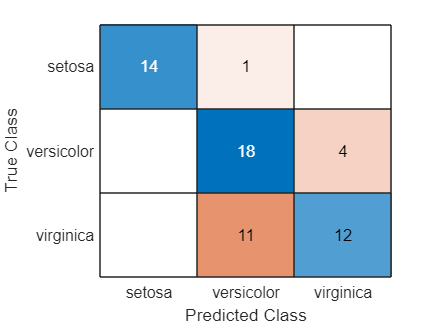


figure; confusionchart(test_labels, predictions)

Check you can answer the questions below by looking at the final confusion matrix:

(**Sanity check**: Investigate the contents of your testing labels array at the command line if you're unsure about the final answer - remember you can call `summary()` on it as it's a categorical array)

% how many versicolor irises are correctly classified?
18

ans = 18

% how many virginica irises are incorrectly classified as being versicolor irises?
11

ans = 11

% how many virginica irises are there in the testing data in total?
23

ans = 23

## k-Nearest Neighbours (k-NN) fitting and model structure

Let's have a look at the important properties of the `ClassificationKNN` object which results from our call to `fitcknn()`. Remember the k-NN training/fitting phase is very simple, just taking a copy of the training examples and training labels, and the hyperparameter k, and storing them: 

m_knn.X % our training examples

ans =     5.2000    3.5000
    6.1000    3.0000
    6.7000    3.3000
    5.4000    3.9000
    7.4000    2.8000
    5.0000    3.5000
    6.0000    2.2000
    5.1000    3.8000
    6.5000    3.2000
    6.2000    2.9000


m_knn.Y % our training labels

ans = 90×1 categorical array
     setosa 
     virginica 
     virginica 
     setosa 
     virginica 
     setosa 
     virginica 
     setosa 
     virginica 
     versicolor 
     versicolor 
     setosa 
     setosa 
     versicolor 
     versicolor 
     virginica 
     virginica 
     versicolor 
     virginica 
     setosa 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     virginica 
     versicolor 


m_knn.NumNeighbors % the number of nearest neighbours we want to use

ans = 1

As with the naive Bayes classifier last time, we're going to preserve the same property names in our own re-implementation (even the American English spelling of "neighbors"). This isn't just for consistency, but because it will simplify some of the tasks we attempt in later labs, allowing us to swap more easily between models we've made ourselves and models created using Matlab's built-in functionality.

## Visualising the feature space

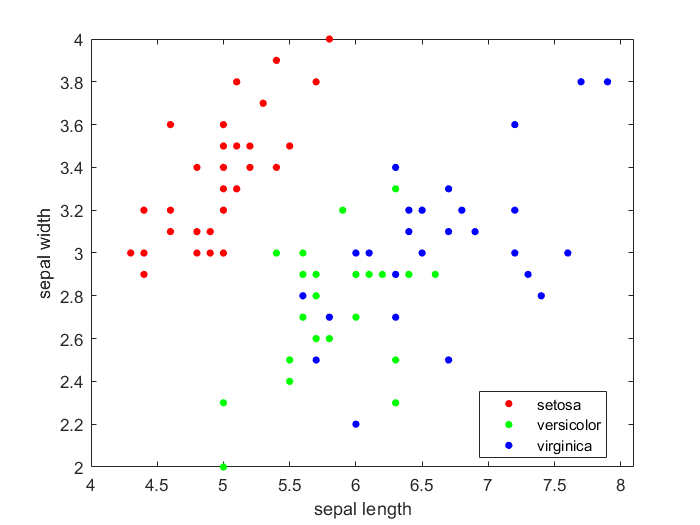

Because our data only contains two features, our feature space is only 2D and we can easily plot it. The code below uses a function called `gscatter()`, short for "grouped scatter plot", to visualise the training examples stored inside the model as points in a 2D feature space, colour coded by their associated class labels:

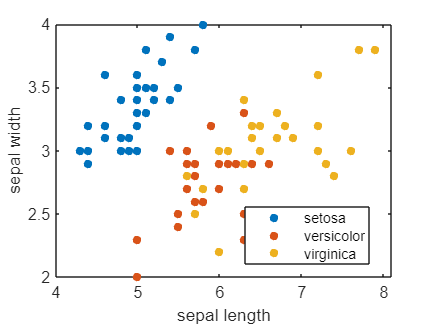

figure;
gscatter(m_knn.X(:,1), m_knn.X(:,2), m_knn.Y);
xlabel('sepal length');
ylabel('sepal width');

## k-NN prediction - thinking it through

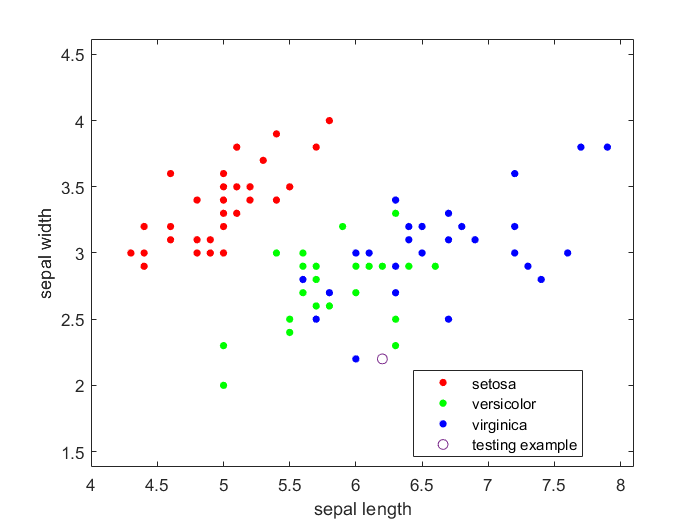

Let's plot a single testing example and think through the k-NN classifier's prediction phase. The code below draws the feature space again, sets the axis scales equal (so we can visually judge distances more easily), and superimposes the 25th testing example as a black circle using a call to the `scatter()` function:

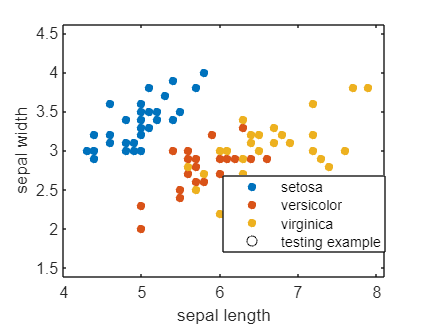

figure;
gscatter(m_knn.X(:,1), m_knn.X(:,2), m_knn.Y);
xlabel('sepal length');
ylabel('sepal width');

% set the scales of the two axes equal to allow easy visual estimation of distances:
axis('equal');
% allow overlaying of plots:
hold('on');
% plot the 25th testing example as a black circle:
scatter(test_examples(25,1), test_examples(25,2), 'ok', 'DisplayName', 'testing example');

If we passed this testing example to the k-NN classifier we trained at the start of the script, then what class label would it predict? 

Have a look at the position of the new testing example, and remember that a k-NN classifier generates its prediction based on the class labels associated with a new testing example's *nearest neighbour(s)*; that is, the training example(s) that lie closest to the testing example in feature space. Because we used the hyperparameter k=1, our classifier considers only the single nearest neighbour.

Use the slider to select an answer:

"versicolor"

ans = "versicolor"

What if we retrained our k-NN classifier using k=3 neighbours? What class label would the k-NN classifier predict:

"versicolor"

ans = "versicolor"

Out of interest, what is the true testing label associated with this testing example (you can echo it out either by typing some code at the Command Window, or by adding some code to the listing above):

"select your answer"

ans = "select your answer"

## k-NN prediction - checking your thinking

Now use the k-NN model trained at the start of the script to predict a class label for the 25th testing example. Then retrain the model using k=3 neighbours and repeat the prediction:

(**Sanity check**: the predictions you generate should agree with the class labels you selected in the dropdowns above)

% add your code on the lines below:
predictions(25,1)

ans = categorical
     versicolor 



m_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 3);

predictions = m_knn.predict(test_examples);
predictions(25,1)

ans = categorical
     versicolor 


## k-NN prediction - starting to code it

In this section we're going to look at identifying nearest neighbours, and generating predictions, programatically. We're repeating the same steps that you performed visually in the earlier section, but this time writing some code to do it, based on the properties of the `ClassificationKNN` object returned by the `fitcknn()` function. 

Matlab has a built-in helper function to do the hard work for us... We'll use it for now and then see if we can replace it with our own code in the later tasks.

The Matlab helper function `knnsearch(A, B)` finds the nearest neighbour in `A` for each point in `B`. In the context of machine learning, the arrays `A` and `B` should store one example per row (exactly as our arrays do). For every example/row in `B`, the function loops over all the examples/rows in array `A` and calculates the Euclidean distance to each one, storing the index of the row/example that returned the smallest result (i.e., was closest).

Have a look at how we can use `knnsearch()` to find the index of the 25th testing example's nearest neighbour amongst the training examples, and then use that index to generate a prediction based on the associated training label:

% find the index of the nearest neighbour in the training examples:
ind = knnsearch(m_knn.X, test_examples(25,:))

ind = 48

% use the nearest neighbour's associated training label as our prediction:
prediction = m_knn.Y(ind)

prediction = categorical
     versicolor 


You can also ask to store the indices of the k nearest rows/examples, by setting the K name-value pair (e.g., `'K', 5`). Add code below to find the indices of the 3 nearest neighbours to our testing example and use them to generate a prediction:

(**Hint**: when there are multiple nearest neighbours (k>1) then you need to find the most frequently associated training label; remember the `mode()` function can do this for you and it also implements sensible conventions for making decisions if there is a tie)

% add your code on the lines below:
ind = knnsearch(m_knn.X, test_examples(25,:), "K",3)

ind =     48     7    15


prediction = mode(m_knn.Y(ind))

prediction = categorical
     versicolor 


## Re-implementing k-NN classification part I

The `my_ClassificationKNN` class contains a simple re-implementation of the k-NN fitting algorithm in its constructor (which remember just stores copies of the training examples and training labels, and the number of neighbours to consider). The `my_fitcknn()` function allows you to instantiate an object from the class by calling with your training examples and training labels (and optionally a NumNeighbors name-value pair if you want to supply one), in just the same way we called `fitcknn()` above:

mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 1);

Again, let's have a quick look at the important properties of the resulting `my_ClassificationKNN` object:

mym_knn.X % our training examples

ans =     5.2000    3.5000
    6.1000    3.0000
    6.7000    3.3000
    5.4000    3.9000
    7.4000    2.8000
    5.0000    3.5000
    6.0000    2.2000
    5.1000    3.8000
    6.5000    3.2000
    6.2000    2.9000


mym_knn.Y % our training labels

ans = 90×1 categorical array
     setosa 
     virginica 
     virginica 
     setosa 
     virginica 
     setosa 
     virginica 
     setosa 
     virginica 
     versicolor 
     versicolor 
     setosa 
     setosa 
     versicolor 
     versicolor 
     virginica 
     virginica 
     versicolor 
     virginica 
     setosa 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     virginica 
     versicolor 


mym_knn.NumNeighbors % the number of nearest neighbours to use

ans = 1

**Get both my_fitcknn.m and my_ClassificationKNN.m opened up in Matlab and spend just a few minutes looking over them.** 

Now reuse your `knnsearch()` code from the previous task to extend the `predict()` method stub in the `my_ClassificationKNN` class so that it uses `knnsearch()` to generate predictions for an array of testing examples. To keep things simple, we recommend making a separate individual call to `knnsearch()` for each testing example (i.e., using a loop over your testing examples, which contains some code for calling `knnsearch()` very similar to the code you wrote for the previous task). This approach will be easier to extend in the next task. (You *can* pass all the testing examples to `knnsearch()` at once if you prefer, but be careful handling the 2D array that comes back (each row contains the indices of the k nearest neighbours).)

Note that because the `my_ClassificationKNN` object sticks to the X and Y naming conventions used by Matlab's classifier objects, and also retains the NumNeighbors name (American English spelling), you should be able to reuse your code from the previous task without any issues.

Add code below to pass your `test_examples` array to your new `my_ClassifierKNN` object's `predict()` method, and generate an overall accuracy score and a confusion matrix. Make sure the K name-value pair used by the `knnsearch()` function is linked to the NumNeighbors property of your class and adjust the above call to `my_fitcknn()` in order to test with k=3 nearest neighbours:

(**Hint**: adding debug as you work is encouraged, but try to keep it under the Verbose option in your class, and call `my_fitcknn()` with the Verbose name-value pair set to true if you want to see it.)

(**Sanity check**: using a single nearest neighbour, you should be able to generate an overall accuracy and confusion matrix that match exactly with what you saw in the first task; using k=3 you should get an overall accuracy of 78.3%)

% add your code on the lines below:
mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 1);
predictions = predict(mym_knn,test_examples,2);
p_knn = sum(predictions == test_labels) / length(test_labels)

p_knn = 0.7333


figure; confusionchart(test_labels, predictions);


mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 3);
predictions =  predict(mym_knn,test_examples,2);
p_knn = sum(predictions == test_labels) / length(test_labels)

p_knn = 0.7833

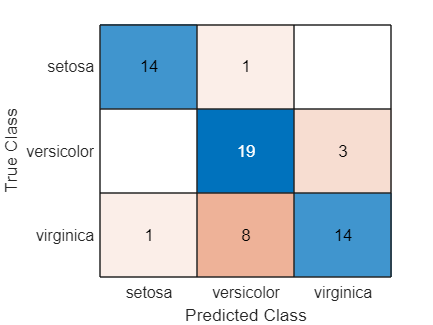


figure; confusionchart(test_labels, predictions)

## Re-implementing k-NN classification part II

Can you now remove your code's dependency on the built-in `knnsearch()` function? For each testing example that is passed to your `predict()` method, this will require looping over all of the training examples, calculating the Euclidean distance to each one, finding the examples with the k smallest distances, and using their associated labels to generate a prediction by calling `mode()`.

Consider making a copy of your working `knnsearch()` implementation before you break things!

Add some code below to check you can get an identical overall accuracy and confusion matrix versus the built-in `fitcknn()` implementation, when using k=3 nearest neighbours:

(**Hint**: adding debug as you work is encouraged, but try to keep it under the Verbose option in your class, and call `my_fitcknn()` with the Verbose name-value pair set to true if you want to see it.)

(**Sanity check**: you should see exact agreement between overall accuracy (78.3%, k=3) and the associated confusion matrices)

% add your code on the lines below:
mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 3);

predict(mym_knn,test_examples,2)

ans = 60×1 categorical array
     virginica 
     versicolor 
     setosa 
     setosa 
     setosa 
     setosa 
     virginica 
     versicolor 
     versicolor 
     virginica 
     virginica 
     virginica 
     setosa 
     setosa 
     versicolor 
     versicolor 
     versicolor 
     setosa 
     versicolor 
     virginica 
     virginica 
     setosa 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     setosa 
     virginica 
     versicolor 
     versicolor 


## A more interesting dataset: biopsies.csv

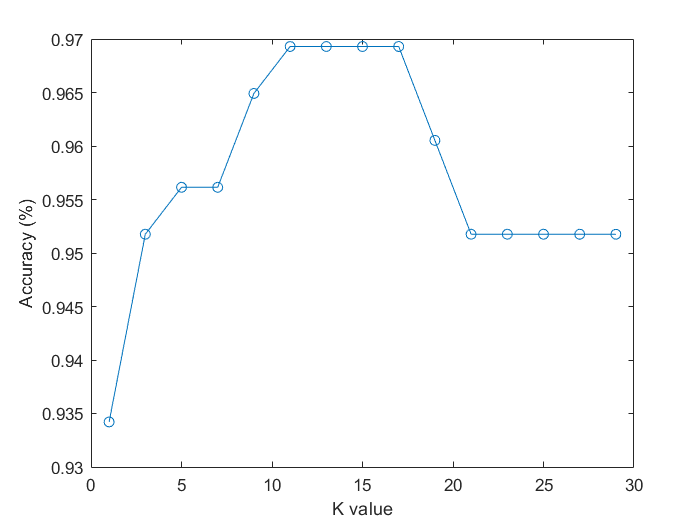

Try your finished implementation on the biopsies.csv dataset using k=1 nearest neighbours, again checking against the results you get against the built-in `fitcknn()` function. Then, ensuring you have taken sensible steps to minimise execution times (e.g., setting Verbose to false), use your implementation to investigate the best value of k to use for this dataset (you should test all odd values between 1 and 30, inclusive):

(**Hint**: consider pre-allocating your arrays for better performance)

(**Sanity check**: You should get an overall classification accuracy of 93.4% using k=1; you should be able to produce a graph like the one above for your investigation of the best k value)

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% read in the dataset:
data = readcell('biopsies.csv');

% add your code on the lines below:

data(1:1:10, 1:1:end)

ans = 10×31 cell array
    {'diagnosis'}    {'radius_mean'}    {'texture_mean'}    {'perimeter_mean'}    {'area_mean'}    {'smoothness_mean'}    {'compactness_mean'}    {'concavity_mean'}    {'concave points_mean'}    {'symmetry_mean'}    {'fractal_dimension_mean'}    {'radius_se'}    {'texture_se'}    {'perimeter_se'}    {'area_se'}    {'smoothness_se'}    {'compactness_se'}    {'concavity_se'}    {'concave points_se'}    {'symmetry_se'}    {'fractal_dimension_se'}    {'radius_worst'}    {'texture_worst'}    {'perimeter_worst'}    {'area_worst'}    {'smoothness_worst'}    {'compactness_worst'}    {'concavity_worst'}    {'concave points_worst'}    {'symmetry_worst'}    {'fractal_dimension_worst'}
    {'Benign'   }    {[    -0.1667]}    {[     -1.1462]}    {[       -0.1856]}    {[  -0.2517]}    {[         0.1017]}    {[         -0.4365]}    {[       -0.2780]}    {[            -0.0286]}    {[       0.2677]}    {[               -0.7277]}    {[  -0.4878]}    {[   -0.7763]}    {[     -0.399


obs = data(2:end,:);

obs_shuffled = obs(randperm(size(obs,1)), :);

nTest = round(0.4 * size(obs_shuffled,1))

nTest = 228

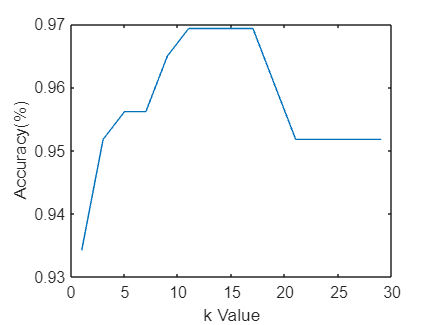


obs_test = obs_shuffled(1:1:nTest, :);
obs_train = obs_shuffled(nTest+1:1:end, :);


test_labels = categorical(obs_test(:, 1));
test_examples = cell2mat(obs_test(:, 2:end));

size(test_examples);
size(test_labels);

train_labels = categorical(obs_train(:, 1));
train_examples = cell2mat(obs_train(:, 2:end));

size(train_examples);
size(train_labels);

for i = 1:2:30
    bio_knn = my_ClassificationKNN(train_examples, train_labels,i, false);
    bio_p = predict(bio_knn,test_examples,30);
    knn = sum(bio_p == test_labels) / length(test_labels);

    k_plot(i,1) = knn;
end   


figure;
plot((1:2:30),k_plot(1:2:30,1));
xlabel('k Value');
ylabel('Accuracy(%)');